 
clear
clf
timerOverall = tic;
fprintf(['Beginning Script...' newline]);

Beginning Script...


[scenario, testName] = oblongTest;
video1 = false;
video2 = false;
video3 = true;
formationGIF = false;

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

normFactor = floor(sVals(end))/sVals(end);

innerBoundsNormalized = innerBounds.*normFactor;
centersNormalized = centers.*normFactor;
outerBoundsNormalized = outerBounds.*normFactor;
sValsNormalized = sVals.*normFactor;

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:sValsNormalized(end))'];

boundaryPointsNormalized = [spline(sValsNormalized, innerBoundsNormalized(:,1), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, innerBoundsNormalized(:,2), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,1), 0:sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,2), 0:sValsNormalized(end))'];

fprintf(['Beginning Optimization...' newline])

Beginning Optimization...


timeOptimization = tic;
[waypointsFit, videoSet, videoSetPt, sFit] = discreteWaypointOptimizer(waypoints, normFactor*3, 50, 0.01, 0.2, 0.2, testName);

Iteration: 1 | k: 9.87920070
Iteration: 2 | k: 9.68792957
Iteration: 3 | k: 9.52287448
Iteration: 4 | k: 9.36161494
Iteration: 5 | k: 9.20520089
Iteration: 6 | k: 9.05448181
Iteration: 7 | k: 8.90961945
Iteration: 8 | k: 8.77076742
Iteration: 9 | k: 8.63784297
Iteration: 10 | k: 8.51121640
Iteration: 11 | k: 8.39095729
Iteration: 12 | k: 8.42271248
Iteration: 13 | k: 8.30562565
Iteration: 14 | k: 8.22530370
Iteration: 15 | k: 8.15763592
Iteration: 16 | k: 8.10121139
Iteration: 17 | k: 7.98465471
Iteration: 18 | k: 7.89885427
Iteration: 19 | k: 7.86971389
Iteration: 20 | k: 7.80115645
Iteration: 21 | k: 7.75630492
Iteration: 22 | k: 7.67250422
Iteration: 23 | k: 7.58705202
Iteration: 24 | k: 7.54981852
Iteration: 25 | k: 7.52757930
Iteration: 26 | k: 7.50512364
Iteration: 27 | k: 7.48096649
Iteration: 28 | k: 7.45826144
Iteration: 29 | k: 7.43410432
Iteration: 30 | k: 7.39423385
Iteration: 31 | k: 7.35834038
Iteration: 32 | k: 7.33627093
Iteration: 33 | k: 7.32724549


fprintf(['Optimization Complete: %f sec' newline],toc(timeOptimization));

Optimization Complete: 113.650887 sec



videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

fprintf(['Beginning Velocity Profiling...' newline])

Beginning Velocity Profiling...


timeVelocity = tic;
% [velocityProfile, minTLap] = velocityProfiler(0.001, [waypointsFit(1:end-1,:); waypointsFit(1:end-1,:); waypointsFit(:,:)], sFit, 4*300, 0.5*300, 300);
[velocityProfile, velocityByS, criticalVelocities, minTLap] = velocityProfilerV2(0.001, waypointsFit, 5, 5*300, 5*300, 300);

Profile 1 Generated...
Profile 2 Generated...
Profile 3 Generated...
Profile 4 Generated...
Profile 5 Generated...
Profile 6 Generated...
Profile 7 Generated...
Profile 8 Generated...
Profile 9 Generated...
Profile 10 Generated...
Profile 11 Generated...
Profile 12 Generated...
Profile 13 Generated...
Profile 14 Generated...
Profile 15 Generated...
Profile 16 Generated...
Profile 17 Generated...
Profile 18 Generated...
Profile 19 Generated...
Profile 20 Generated...
Profile 21 Generated...
Profile 22 Generated...
Profile 23 Generated...
Profile 24 Generated...
Profile 25 Generated...
Profile 26 Generated...
Profile 27 Generated...
Profile 28 Generated...
Profile 29 Generated...
Profile 30 Generated...
Profile 31 Generated...
Profile 32 Generated...
Profile 33 Generated...
Profile 34 Generated...
Profile 35 Generated...
Profile 36 Generated...
Profile 37 Generated...
Profile 38 Generated...
Profile 39 Generated...
Profile 40 Generated...
Profile 41 Generated...
Profile 42 Generated...
P

fprintf(['Velocity Profiling Complete: %f sec' newline], toc(timeVelocity));

Velocity Profiling Complete: 66.895723 sec


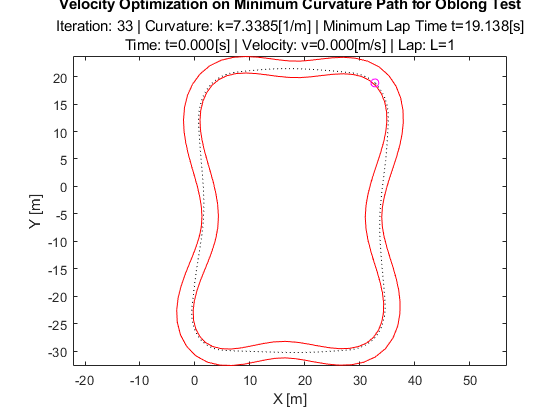

Beginning Video Output By Velocity...


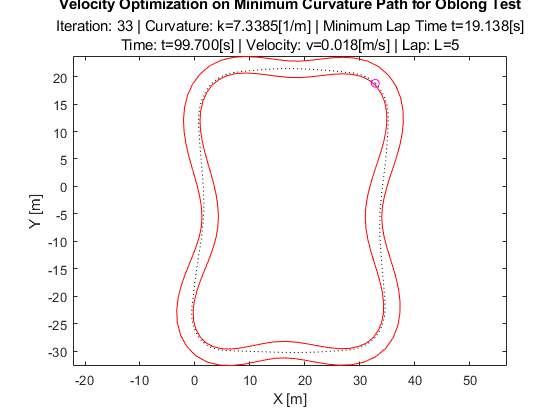

Velocity Video Complete: 743.252947 sec



iterationEnd = videoSet{end,2};
curvatureEnd = videoSet{end,3};

if video1
    fprintf(['Beginning Video Output By Iteration...' newline]);
    timeVideo1 = tic;
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    fprintf(['Iteration Video Complete: %f sec' newline],toc(timeVideo1));
end

if video2
    fprintf(['Beginning Video Output By Point...' newline]);
    timeVideo2 = tic;
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    fprintf(['Point Video Complete: %f sec' newline],toc(timeVideo2));
end

if video3
    fprintf(['Beginning Video Output By Velocity...' newline]);
    timeVideo3 = tic;
    writer3(velocityProfile, 40, testName, waypointsFit, innerBounds, outerBounds, minTLap, iterationEnd, curvatureEnd);
    timeVideo3Out = toc(timeVideo3);
    fprintf(['Velocity Video Complete: %f sec' newline],timeVideo3Out);
end


if formationGIF
    fprintf(['Beginning GIF Output...' newline]);
    timeGIF = tic;
    gifWriter(videoSet, testName, boundaryPointsNormalized/normFactor, normFactor)
    timeGIFOut = toc(timeGIF);
    fprintf(['GIF Complete: %f sec' newline],timeGIFOut);
end


if ~video1 && ~video2 && ~video3 && ~formationGIF
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        waypointsFit(:,1), waypointsFit(:,2), 'm',...
        'Visible',"on");
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' | Curvature: k=',num2str(videoSet{end,3})]);
    axis equal;
end

fprintf(['Script Complete: %f sec' newline], toc(timerOverall))

Script Complete: 924.123009 sec


function writer1(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer3(videoSet, fps, testName, minCurPath, innerBounds, outerBounds, minTLap, itEnd, kEnd)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByVel']);
writer.FrameRate = fps;
skipFactor = (1/fps)*(1/(videoSet(2,2)-videoSet(1,2)));
open(writer);
for idxVidSet = 1:skipFactor:size(videoSet,1)
    plot(minCurPath(:,1), minCurPath(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet(idxVidSet,4), videoSet(idxVidSet,5), 'mo',...
        'Visible',"on");
    hold on
    title(['Velocity Optimization on Minimum Curvature Path for ',testName],['Iteration: ',num2str(itEnd,'%.0f'),' | Curvature: k=',num2str(kEnd),'[1/m] | Minimum Lap Time t=',num2str(minTLap,'%.3f'),'[s]', newline,'Time: t=',num2str(videoSet(idxVidSet,2),'%.3f'),'[s] | Velocity: v=',num2str(videoSet(idxVidSet,1),'%.3f'), '[m/s] | Lap: L=',num2str(videoSet(idxVidSet,8),'%.0f')]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function gifWriter(videoSet, testName, inOutBounds, normFactor)
clf;
fileName = [testName(testName ~= ' '), '.gif'];
plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
     inOutBounds(:,3), inOutBounds(:,4), 'r');
title(['Curvature Optimization on ',testName],['Iteration: 0 | Curvature: k=0.000']);
axis equal;
xlabel('X [m]');
ylabel('Y [m]');
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','LoopCount',Inf,'DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['emptyTrack', testName(testName ~= ' '), '.png']);
hold on
plot(videoSet{1,1}(:,1), videoSet{1,1}(:,2), ' *m', 'MarkerSize', 1);
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['trackWaypoints', testName(testName ~= ' '), '.png']);
for idxWP = 1:length(videoSet{1,1})-1
    angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));   
    rotLinePoints = [0, (-normFactor*3/2)*(1-0.2); 0, (normFactor*3/2)*(1-0.2)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
    plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
end
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['waypointChords', testName(testName ~= ' '), '.png']);
hold off

for idxVidSet = 1:size(videoSet,1)
    plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
        inOutBounds(:,3), inOutBounds(:,4), 'r');
    hold on
    for idxWP = 1:length(videoSet{1,1})-1
        angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));
        rotLinePoints = [0, (-normFactor*3/2)*(1-0.2); 0, (normFactor*3/2)*(1-0.2)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
        plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
    end
    plot(videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    [gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
    imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',0.25);
end
imwrite(frame2im(getframe(gcf)), ['waypointFinal', testName(testName ~= ' '), '.png']);
end
% [ai] a(v=0) = 0
% [av] a(v=20) = 3
% [am] a(v=40) = 6
% da/dv = ra((am-a)/am)
% da/dt max = 2
% dv/dt max = 5
% dp/dt max = 40
% a = am/(1+be^(-kv))
% 